% Example_4_1.mlx
%
% This is Example 4.1 from the paper 'Geometric modelling of 
% polycrystalline materials: Laguerre tessellations and periodic 
% semi-discrete optimal transport' by D.P. Bourne, M. Pearce & S.M. Roper.
%
% We generate a 3D periodic Laguerre diagram with 10,000 grains of given 
% volumes, where the grain volumes are drawn from a log-normal 
% distribution, using the algorithm from Section 4 of the above paper. 

clear

tic

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

n=10000; % number of grains

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Specify whether the Laguerre diagram is periodic (periodic=true) or
% non-periodic (periodic=false)

periodic=true; 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Define the geometry. We create a 3D periodic Laguerre diagram in a 
% rectangular box with vertices (0,0,0), (L1,0,0), (0,L2,0), (0,0,L3), 
% (L1,L2,0), (L1,0,L3), (0,L2,L3), (L1,L2,L3).

L1=2; % length of the box in the x-direction
L2=2; % length of the box in the y-direction
L3=2; % length of the box in the z-direction
bx=[L1,L2,L3];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Specify the desired volumes of the grains, which are drawn from a 
% log-normal distribution

ln_mean=1; % mean
std_dev=0.35; % standard deviation
Sigma=sqrt((log(1+(std_dev/ln_mean)^2))); % log-normal parameter sigma
Mu=-0.5*Sigma^2+log(ln_mean); % log-normal parameter mu

% Draw the radii from the log-normal distribution
radii=lognrnd(Mu,Sigma,[n,1]);

% Calculate the corresponding grain volumes 
% (note that we don't need the factor 4pi/3 as we'll be renormalising)
target_vols=radii.^3;

% Normalise the volumes so that they add to the volume of the box
target_vols=...
    target_vols*L1*L2*L3/sum(target_vols); % target volumes of the grains          

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Perform the algorithm from Section 4 of the paper 'Geometric modelling 
% of polycrystalline materials: Laguerre tessellations and periodic 
% semi-discrete optimal transport' by D.P. Bourne, M. Pearce & S.M. Roper.

% Set the parameters of the algorithm
numLloyd=5; % number of regularisation (Lloyd) iterations
tol=1; % percentage error tolerance for the volumes of the grains

% Initialise the seed locations randomly
x0=L1*rand(n,1); % x-coordinates
y0=L2*rand(n,1); % y-coordinates
z0=L3*rand(n,1); % z-coordinates
Y=[x0,y0,z0]; % initial seed locations

% Initialise the weights
w=zeros(n,1);

% Iterative method
for m=1:numLloyd

    % 1. Regularisation step: move the seeds to the centroids of the grains
    [~,~,Y]=mexPD(bx,Y,w,periodic);
    % 2. Damped Newton step: find weights w so that grains have target vols
    [w,percent_error,actual_vols,~]=...
        SDOT_damped_Newton(zeros(n,1),Y,target_vols,bx,periodic,tol);

end

% Output the difference (percentage error) between the actual volumes of 
% the grains and the target volumes 
disp(strcat('Maximum percentage error=',num2str(percent_error),'%'));

Maximum percentage error=0.0085754%



toc

Elapsed time is 51.876470 seconds.


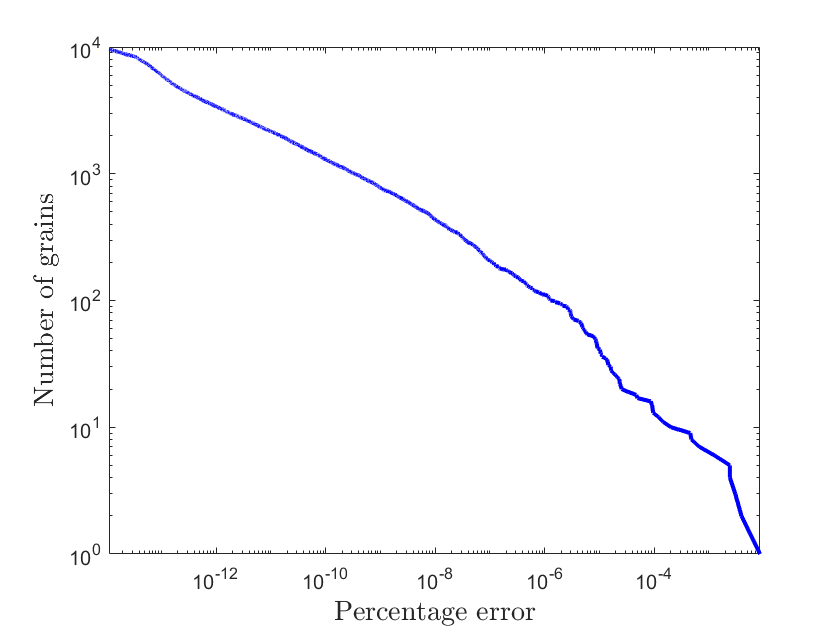


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot the volume errors

percentage_errors=100*abs(actual_vols-target_vols)./target_vols;
plotErrors(percentage_errors);

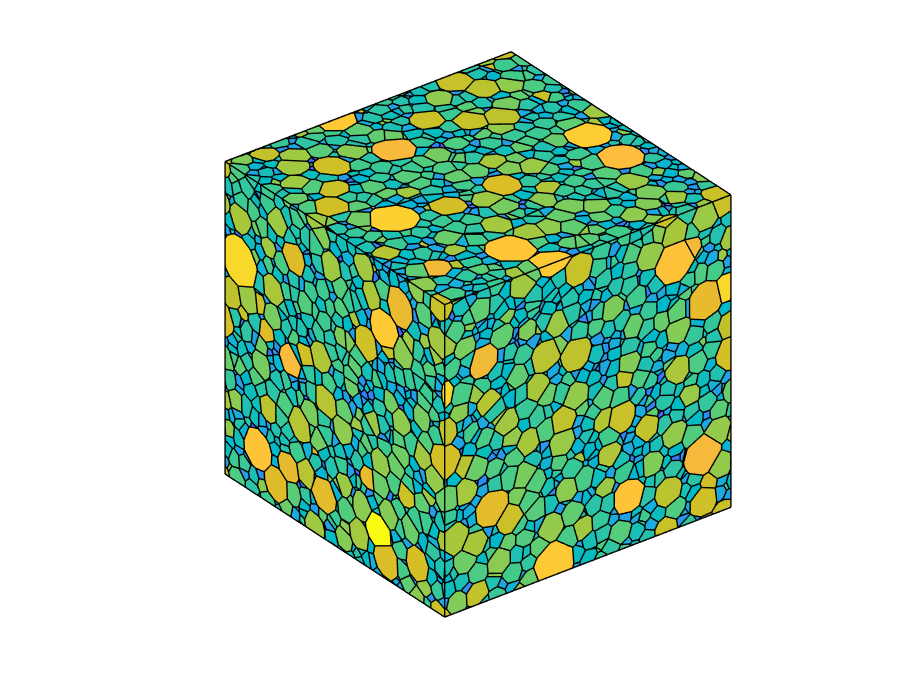

drawnow

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Plot the Laguerre tessellation

% Compute the vertices, faces, neighbours (vfn) of the Laguerre diagram
[~,~,~,vfn]=mexPDall(bx,Y,w,periodic); 

% Compute which cells lie on the boundary of the box (no need to plot the 
% interior cells since they are not visible)
[polys,cellids]=intersect_cells_on_boundary_periodic(bx,vfn);

% Colour the grains according to their volume, using a log scale
colormap=parula;
myc=generateGrainColours(log(actual_vols));

% Plot the Laguerre tessellation
figure
patchpolygons(polys,cellids,myc);
view([-37.5,30])
axis equal
axis off